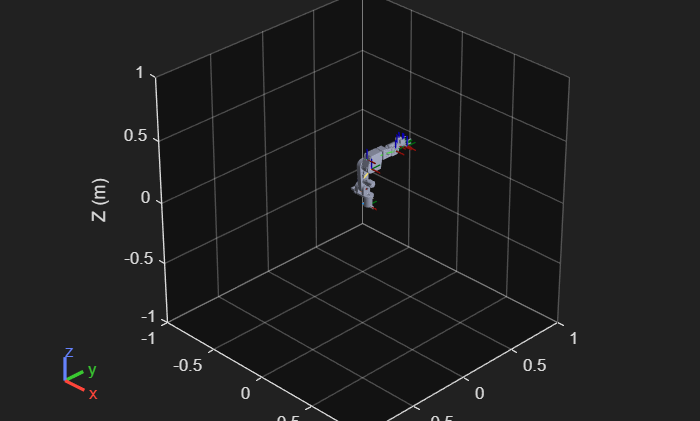

% Shows robot in home position
clear; close all; clc;

% where the urdf and meshes are located, change to your location
try
    urdfFile = 'C:\Users\matte\Documents\Open-robot-arm\Software\robotarm\urdf\robot_armV2.SLDASM.urdf';
    meshPath = 'C:\Users\matte\Documents\Open-robot-arm\Software\robotarm\meshes';
catch ME
    fprintf("Error:")
    disp(ME.identifier)
end


robot = importrobot(urdfFile, 'MeshPath', meshPath);
homeConfig = homeConfiguration(robot);
% Displays the robot
figure;
show(robot, homeConfig);
title('My Robot - Home Position');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
grid on;
view(45, 30);


%information about the robot
fprintf('   Robot Base Name: %s\n', robot.BaseName);

   Robot Base Name: base_link


fprintf('   Number of Bodies: %d\n', numel(robot.Bodies));

   Number of Bodies: 12


fprintf('   Number of Joints: %d\n', numel(robot.Bodies));

   Number of Joints: 12


fprintf('   Data Format: %s\n\n', robot.DataFormat);

   Data Format: struct




fprintf('┌────┬─────────────────────┬─────────────┬──────────────────────┬─────────────────┐\n');

┌────┬─────────────────────┬─────────────┬──────────────────────┬─────────────────┐


fprintf('│ #  │ Joint Name          │ Type        │ Home Position        │ Limits [rad]    │\n');

│ #  │ Joint Name          │ Type        │ Home Position        │ Limits [rad]    │


fprintf('├────┼─────────────────────┼─────────────┼──────────────────────┼─────────────────┤\n');

├────┼─────────────────────┼─────────────┼──────────────────────┼─────────────────┤



for i = 1:numel(robot.Bodies)
    body = robot.Bodies{i};
    jointName = body.Joint.Name;
    jointType = body.Joint.Type;
    
    % Get home position for this joint
    homePos = homeConfig(i).JointPosition;
    
    % Get joint limits if available
    if strcmp(jointType, 'revolute') || strcmp(jointType, 'prismatic')%cheks if the jointType == revolut or prismatic, strcmp cheks if 2 strings are equal
        limits = body.Joint.PositionLimits;
        fprintf('│ %-2d │ %-19s │ %-11s │ %8.4f rad (%6.2f°) │ [%6.2f, %6.2f] │\n', ...
            i, jointName, jointType, homePos, rad2deg(homePos), limits(1), limits(2));
    elseif strcmp(jointType, 'fixed')
        fprintf('│ %-2d │ %-19s │ %-11s │       FIXED          │      FIXED      │\n', ...
            i, jointName, jointType);
    else
        fprintf('│ %-2d │ %-19s │ %-11s │ %8.4f rad (%6.2f°) │      N/A        │\n', ...
            i, jointName, jointType, homePos, rad2deg(homePos));
    end
end

│ 1  │ shoulder_joint1     │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 2  │ shoulder_joint2     │ revolute    │   0.0000 rad (  0.00°) │ [ -1.57,   1.57] │
│ 3  │ elbow_joint         │ revolute    │   0.0000 rad (  0.00°) │ [ -1.57,   1.57] │
│ 4  │ wrist_turn_joint    │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 5  │ wrist_tilt_joint    │ revolute    │   0.0000 rad (  0.00°) │ [ -2.09,   1.57] │
│ 6  │ gripper_turn_joint  │ revolute    │   0.0000 rad (  0.00°) │ [  -Inf,    Inf] │
│ 7  │ gripper_left_drive_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 8  │ gripper_left_finger_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 9  │ gripper_left_support_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [  0.00,   0.00] │
│ 10 │ gripper_right_drive_arm_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15708.00, 15708.00] │
│ 11 │ gripper_right_finger_joint │ revolute    │   0.0000 rad (  0.00°) │ [-15